%Contrast enhancement of color images is typically done by transforming 
% an image to a color space that has image intensity as one of its components. 
% One such color space is L*a*b*. Use color transform functions to convert 
% the image from RGB to L*a*b* color space, and then work on the luminosity layer 'L*' of the image. 
% Manipulating luminosity affects the intensity of the pixels, while preserving the original colors.
% Source: MATLAB Documentation

shadow = imread("lowlight.png");
shadow_lab = rgb2lab(shadow);

% the values of luminosity can span a range from 0 to 100; scale them
% to [0 1] range (appropriate for MATLAB intensity images of class double) 
% before applying the three contrast enhancement techniques
max_luminosity = 100;
L = shadow_lab(:,:,1)/max_luminosity;

% replace the luminosity layer with the processed data and then convert
% the image back to the RGB colorspace
shadow_imadjust = shadow_lab;
shadow_imadjust(:,:,1) = imadjust(L)*max_luminosity;
shadow_imadjust = lab2rgb(shadow_imadjust);

shadow_histeq = shadow_lab;
shadow_histeq(:,:,1) = histeq(L)*max_luminosity;
shadow_histeq = lab2rgb(shadow_histeq);

shadow_adapthisteq = shadow_lab;
shadow_adapthisteq(:,:,1) = adapthisteq(L)*max_luminosity;
shadow_adapthisteq = lab2rgb(shadow_adapthisteq);

% Histogram Equalization: https://homepages.inf.ed.ac.uk/rbf/HIPR2/histeq.htm

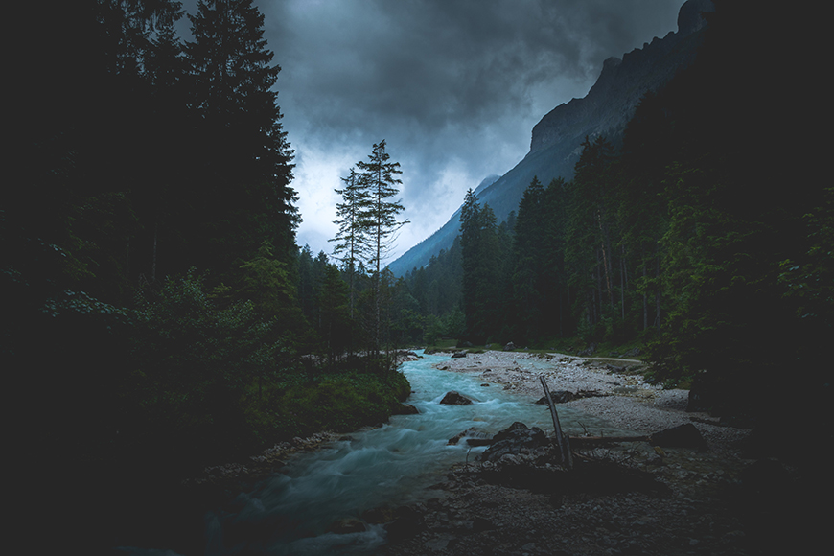

imshow(shadow);

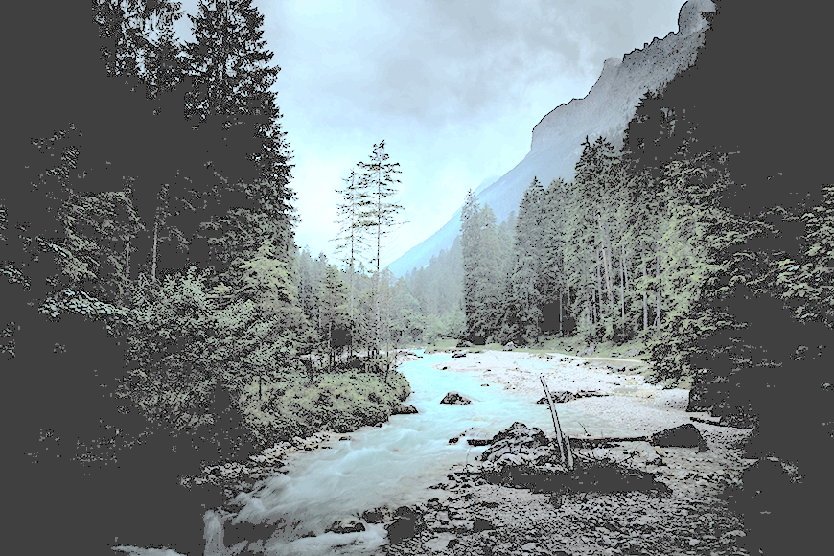

imshow(shadow_histeq);

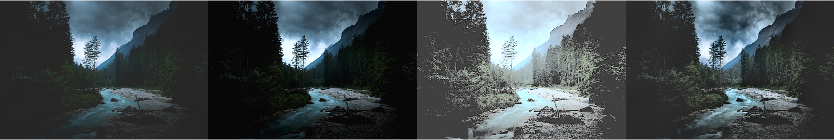

montage({shadow,shadow_imadjust,shadow_histeq,shadow_adapthisteq},"Size",[1 4])
title("Original Image and Enhanced Images using " + ...
    "imadjust, histeq, and adapthisteq")